# Plant Model

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.

plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant)
clear plantPath latestPlant

# Globals

t_final = 10;
delta_t = 0.005;
t = 0:delta_t:t_final;

# Input Signals

inputPath = strcat(commonPath,'\Performance Input Signals\');
latestSlow = latestTimeParse(inputPath,'performanceInputsSlow');
latestFast = latestTimeParse(inputPath,'performanceInputsFast');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestSlow)
load(latestFast)
load(latestPureSin)
clear inputPath latestSlow latestFast latestPureSin

# Data

%Smooth Stability Data
inputPath = strcat(commonPath,'\Stability Sweep Data\');
latestStability = latestTimeParse(inputPath,'stabilitySweep');
load(latestStability)

%Smooth Performance Data
inputPath = strcat(commonPath,'\Smooth Performance Results\');
latestPerformance = latestTimeParse(inputPath,'performanceSweep');
load(latestPerformance)
clear inputPath latestStability latestPerformance

# Export_Fig for Surface Plots

%This toggles the exportfig commands throughout this file.  1 enables, 0
%disables.
figurePath = strcat(commonPath,'\Golden Figures\');

eftoggle = 0;

# Stability Plots

## Nyquist (Delay)

%PI controller
Kp = 1;
Ki = 10;
C_tf = tf([Kp Ki],[1 0]);

%Delay
td = [0.04 0.086 0.093];
linecolors = [{'k'} {'b'} {'r'}];
figure('Renderer', 'painters', 'Position', [10 10 1000 700])
hold on
w = logspace(0,11,1000);
for i = 1:size(td,2)
    %Delay (Pade approximation)
    [nump,denp]=pade(td(i),3);
    d_tf = tf(nump,denp);
    
    %Open and Closed Loop Transfer Functions
    num = C_tf*G_plant;
    oltf = num*d_tf;
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Nyquist
    [re,im] = nyquist(oltf,w);
    re = squeeze(re);
    im = squeeze(im);
    plot(re,im,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    plot(re,-im,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    
end
plot(-1,0,'r+')
xlim([-2,.25])
ylim([-1,1])
yline(0,':k');
xline(0,':k');
xline(-1,'r--');
hold off
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel({'Real Axis','K_p = 1 , K_i = 10'},'FontName','Helvetica','FontSize',22,'FontWeight','bold','Color','k')
ylabel('Imaginary Axis','FontName','Helvetica','FontSize',22,'FontWeight','bold')
legend([ax.Children(9),ax.Children(7),ax.Children(5)],{'Delay = 0.04s (Stable)','Delay = 0.085s (Marginally Stable)','Delay = 0.09s (Unstable)'},'FontName','Helvetica','FontSize',18,'EdgeColor','k')
box on
savePath =strcat(figurePath,'\Smooth Stability\NyquistDelay')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Stability\NyquistDelay'

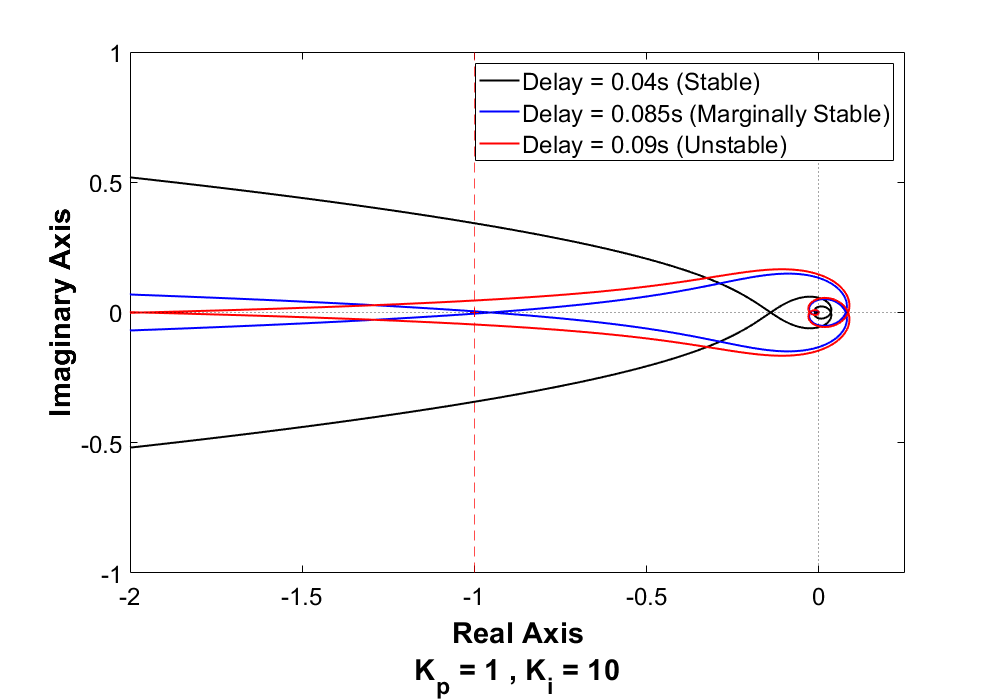

export_fig (savePath,'-eps')

## Nyquist (Proportional Gain)

%PI controller
Kp = [1 9 10];
Ki = 10;


%Delay
td = 0.04;
linecolors = [{'k'} {'b'} {'r'}];
figure('Renderer', 'painters', 'Position', [10 10 1000 700])
hold on
w = logspace(0,11,1000);
for i = 1:size(Kp,2)
    C_tf = tf([Kp(i) Ki],[1 0]);
    %Delay (Pade approximation)
    [nump,denp]=pade(td,3);
    d_tf = tf(nump,denp);
    
    %Open and Closed Loop Transfer Functions
    num = C_tf*G_plant;
    oltf = num*d_tf;
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Nyquist
    [re,im,w] = nyquist(oltf,w);
    re = squeeze(re);
    im = squeeze(im);
    plot(re,im,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    plot(re,-im,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    
end
plot(-1,0,'r+')
xlim([-1.5,.5])
ylim([-1,1])
yline(0,':')
xline(0,':')
xline(-1,'r--')
hold off
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel({'Real Axis','K_i = 10 , Delay = 0.04s'},'FontName','Helvetica','FontSize',22,'FontWeight','bold','Color','k')
ylabel('Imaginary Axis','FontName','Helvetica','FontSize',22,'FontWeight','bold')
legend([ax.Children(9),ax.Children(7),ax.Children(5)],{'K_p = 1 (Stable)','K_p = 9 (Marginally Stable)','K_p = 10 (Unstable)'},'FontName','Helvetica','FontSize',18,'EdgeColor','k')
box on
savePath =strcat(figurePath,'\Smooth Stability\NyquistProportional')
export_fig (savePath,'-eps')

## Nyquist (Integral Gain)

%PI controller
Kp = 1;
Ki = [10 23 30];


%Delay
td = 0.04;
linecolors = [{'k'} {'b'} {'r'}];
figure('Renderer', 'painters', 'Position', [10 10 1000 700])
hold on
w = logspace(0,11,1000);
for i = 1:size(Ki,2)
    C_tf = tf([Kp Ki(i)],[1 0]);
    %Delay (Pade approximation)
    [nump,denp]=pade(td,3);
    d_tf = tf(nump,denp);
    
    %Open and Closed Loop Transfer Functions
    num = C_tf*G_plant;
    oltf = num*d_tf;
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Nyquist
    [re,im,w] = nyquist(oltf,w);
    re = squeeze(re);
    im = squeeze(im);
    plot(re,im,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    plot(re,-im,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    
end
plot(-1,0,'r+')
xlim([-1.5,.5])
ylim([-1,1])
yline(0,':')
xline(0,':')
xline(-1,'r--')
hold off
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel({'Real Axis','K_p = 1, Delay = 0.04s'},'FontName','Helvetica','FontSize',22,'FontWeight','bold','Color','k')
ylabel('Imaginary Axis','FontName','Helvetica','FontSize',22,'FontWeight','bold')
legend([ax.Children(9),ax.Children(7),ax.Children(5)],{'K_i = 10 (Stable)','K_i = 23 (Marginally Stable)','K_i = 30 (Unstable)'},'FontName','Helvetica','FontSize',18,'EdgeColor','k')
box on
savePath =strcat(figurePath,'\Smooth Stability\NyquistIntegral')
export_fig (savePath,'-eps')

## Bode Plot (Delay 0.04, Ki = 10, Kp = 1)

%PI controller
Kp = 1;
Ki = 10;
C_tf = tf([Kp Ki],[1 0]);

%Delay (Pade approximation)
td = 0.04;
[nump,denp]=pade(td,3);
d_tf = tf(nump,denp);

%Open and Closed Loop Transfer Functions
num = C_tf*G_plant;
oltf = num*d_tf;
den = (1 + oltf);
cl_tf = num/den;

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
margin(cl_tf)

## Delay Stability Surface

sf = fit([stabletip(:,1), stabletip(:,2)],stabletip(:,3),'cubicinterp');
figure('Renderer', 'painters', 'Position', [10 10 1000 700])
set(gcf, 'Color', 'w');
plot(sf)% [stabletip(:,1), stabletip(:,2)],stabletip(:,3))
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
ax.ZAxis.FontSize = 18;
ax.ZAxis.FontName = 'Helvetica';
ax.ZAxis.Color = 'k';
xlabel('K_P','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('K_I','FontName','Helvetica','FontSize',22,'FontWeight','bold')
zlabel('Maximum Stable Delay (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
box on

view(-30,25)
savePath =strcat(figurePath,'\Smooth Stability\MaxStableDelayLeft')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Stability\MaxStableDelayLeft'

export_fig (savePath,'-eps')


view(30,25)
savePath =strcat(figurePath,'\Smooth Stability\MaxStableDelayRight')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Stability\MaxStableDelayRight'

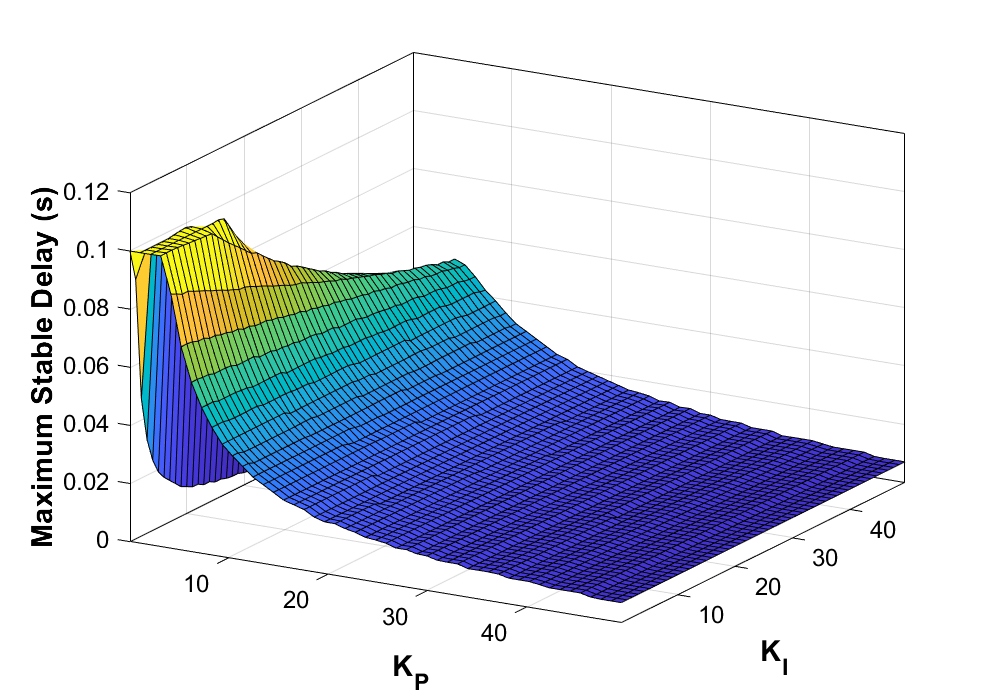

export_fig (savePath,'-eps')

# Performance Plots

## Time

t_final = 10;
delta_t = 0.005;
t = 0:delta_t:t_final;

## Input Signal 1: Chirp

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(t,chirps_slow,'LineWidth',1.5)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
xlabel({'Time (s)','Chirp Input'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
savePath =strcat(figurePath,'\Smooth Performance\InputChirpSlow')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\InputChirpSlow'

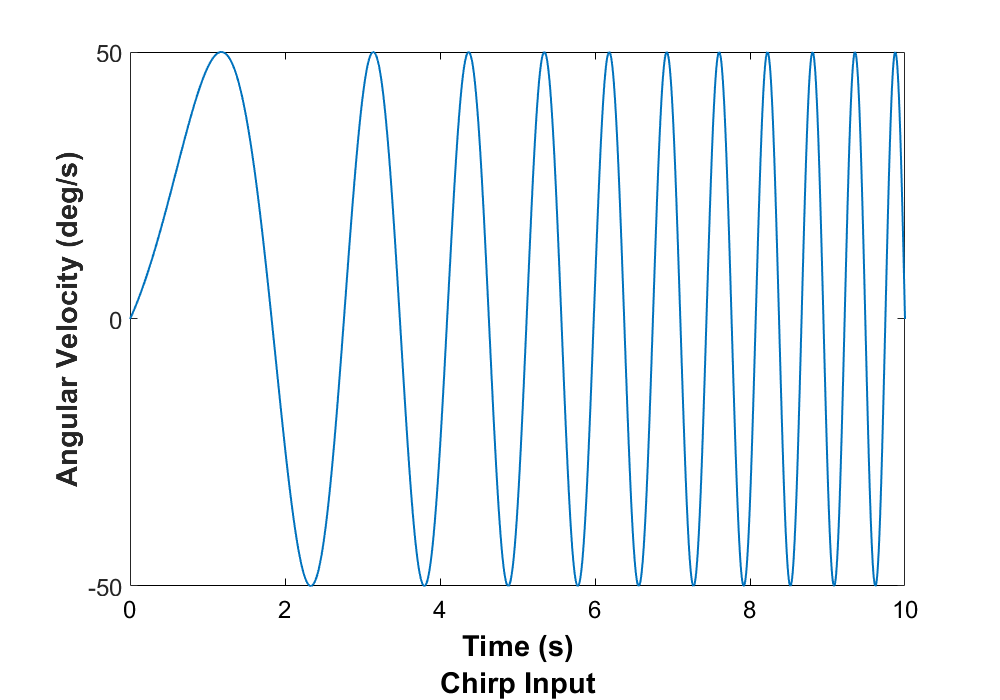

export_fig (savePath,'-eps')


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(t,chirps_fast,'LineWidth',1.5)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
xlabel({'Time (s)','Chirp Input'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
savePath =strcat(figurePath,'\Smooth Performance\InputChirpFast')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\InputChirpFast'

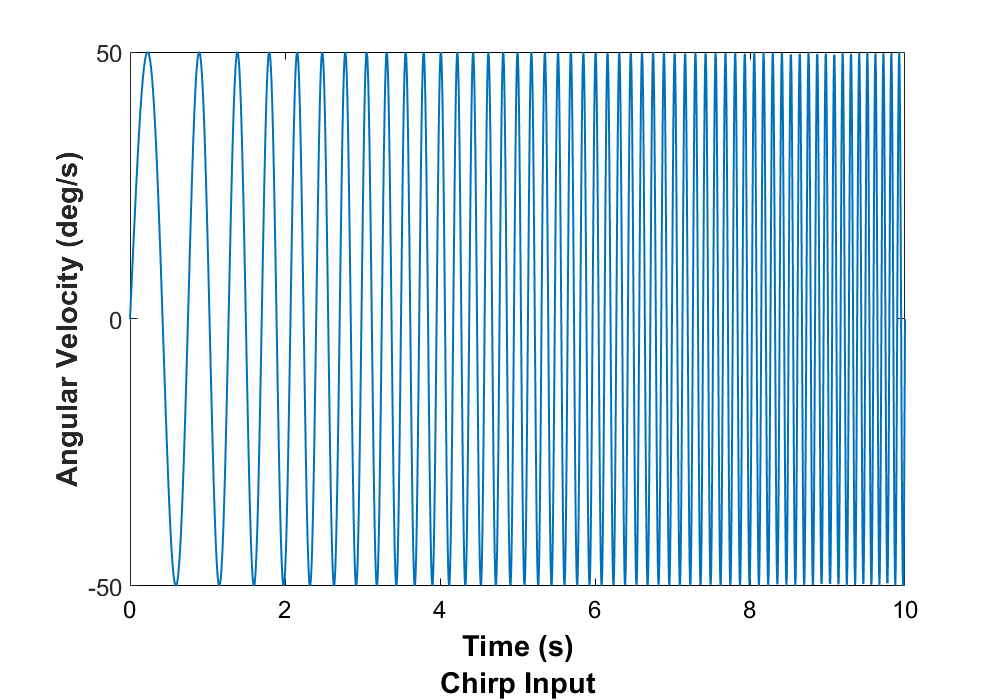

export_fig (savePath,'-eps')

## Input Signal 2: SoS

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(t,sos_slow,'LineWidth',1.5)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
xlabel({'Time (s)','Sum of Sines Input'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
savePath =strcat(figurePath,'\Smooth Performance\InputSoSSlow')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\InputSoSSlow'

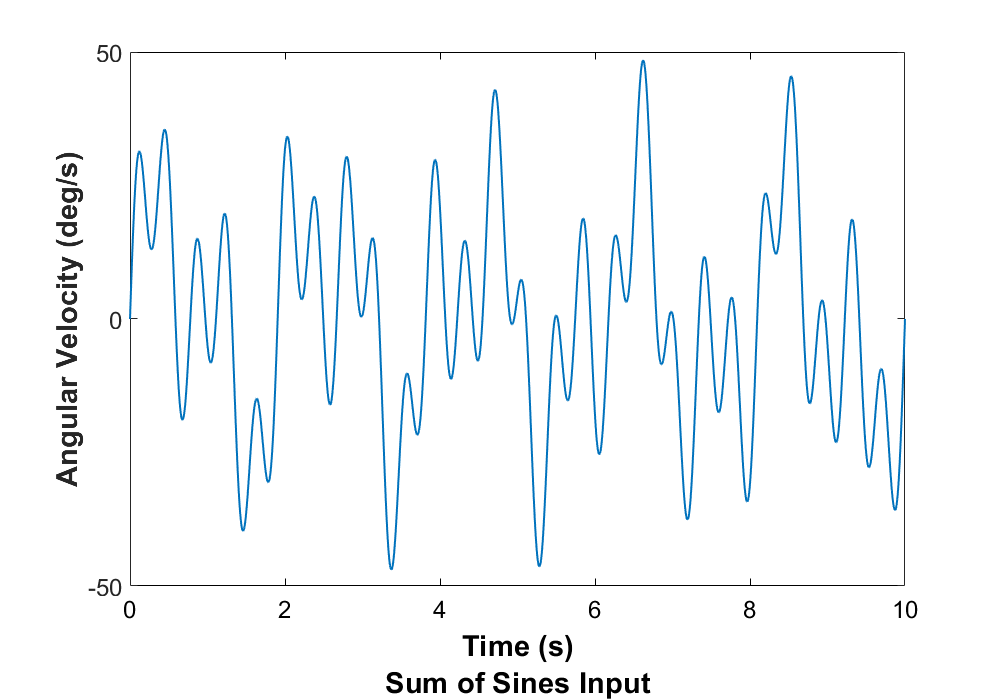

export_fig (savePath,'-eps')


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(t,sos_fast,'LineWidth',1.5)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
xlabel({'Time (s)','Sum of Sines Input'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
savePath =strcat(figurePath,'\Smooth Performance\InputSoSFast')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\InputSoSFast'

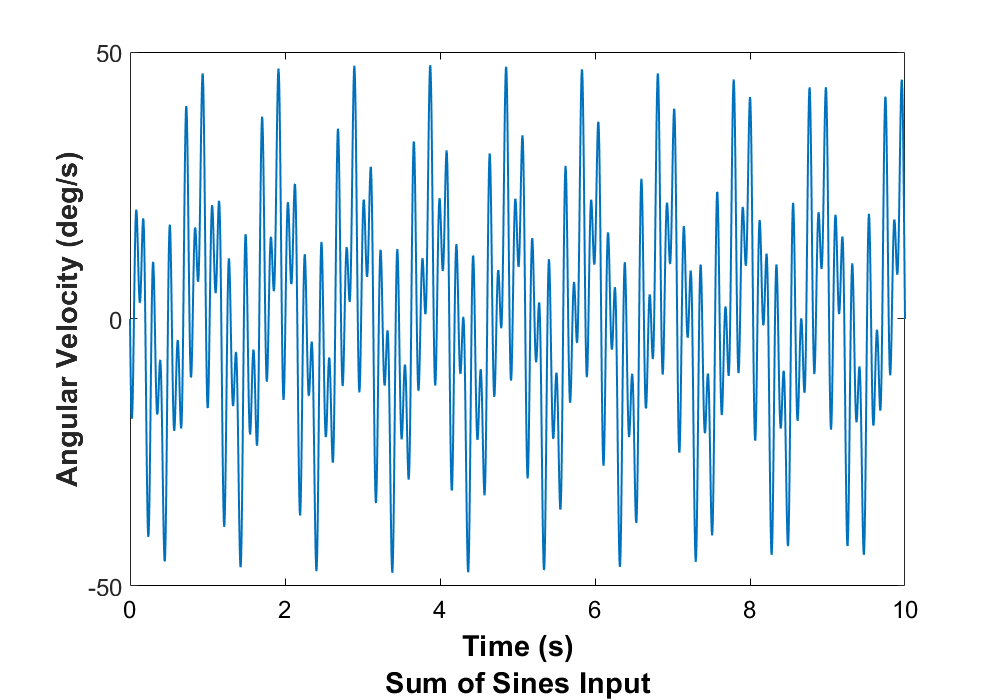

export_fig (savePath,'-eps')

## Input Signal 3: Step

stepin = scale*ones(size(t));
figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(t,stepin,'LineWidth',1.5)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
xlabel({'Time (s)','Step Input'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylim([0,60])
savePath =strcat(figurePath,'\Smooth Performance\InputStep')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\InputStep'

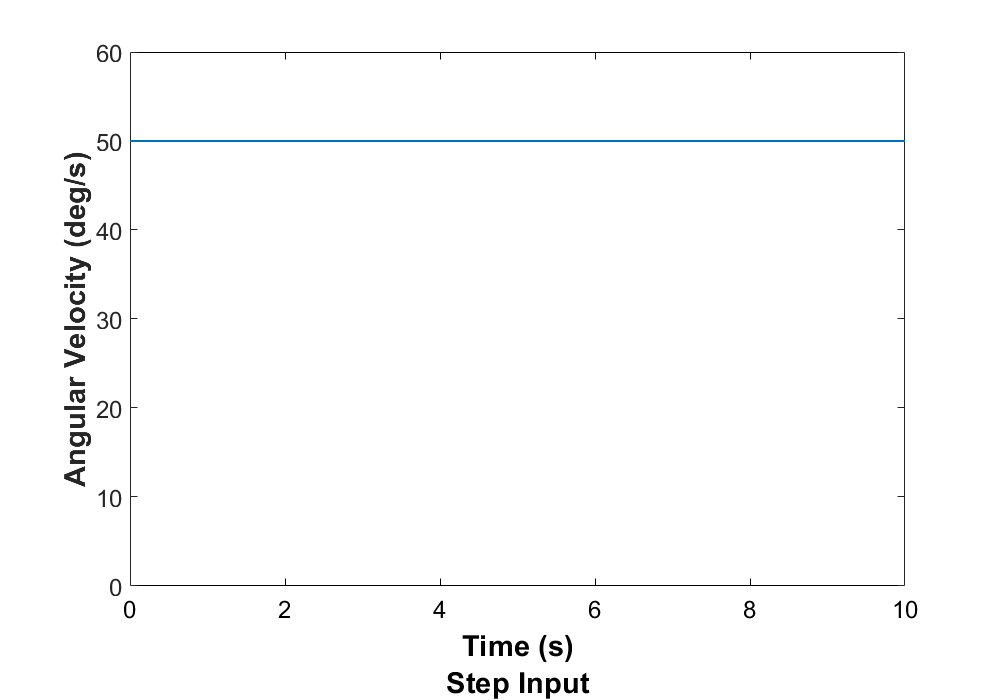

export_fig (savePath,'-eps')

## 0.04 Delay (standard for fly)

ind04 = 1;

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chirperror04 = zerostrip(chirprmses(:,:,ind04));
sfchirp = fit([chirperror04(:,1),chirperror04(:,2)],chirperror04(:,3),'cubicinterp');
plot(sfchirp)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
ax.ZAxis.FontSize = 18;
ax.ZAxis.FontName = 'Helvetica';
ax.ZAxis.Color = 'k';
xlabel('K_P','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('K_I','FontName','Helvetica','FontSize',22,'FontWeight','bold')
zlabel('Chirp RMSE','FontName','Helvetica','FontSize',22,'FontWeight','bold')
box on
view(-45,15)
savePath =strcat(figurePath,'\Smooth Performance\ChirpRMSE')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\ChirpRMSE'

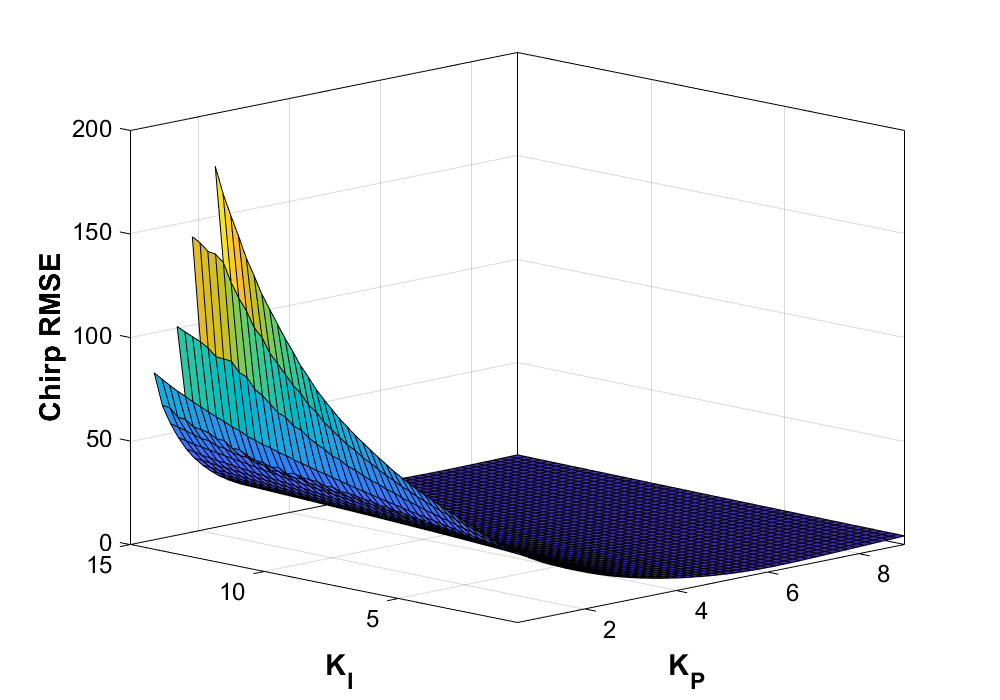

export_fig (savePath,'-eps')




figure('Renderer', 'painters', 'Position', [10 10 1000 700])
soserror04 = zerostrip(sosrmses(:,:,ind04));
sfsos = fit([soserror04(:,1),soserror04(:,2)],soserror04(:,3),'cubicinterp');
plot(sfsos)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
ax.ZAxis.FontSize = 18;
ax.ZAxis.FontName = 'Helvetica';
ax.ZAxis.Color = 'k';
xlabel('K_P','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('K_I','FontName','Helvetica','FontSize',22,'FontWeight','bold')
zlabel('SoS RMSE','FontName','Helvetica','FontSize',22,'FontWeight','bold')
box on
view(-45,15)
savePath =strcat(figurePath,'\Smooth Performance\SoSRMSE')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\SoSRMSE'

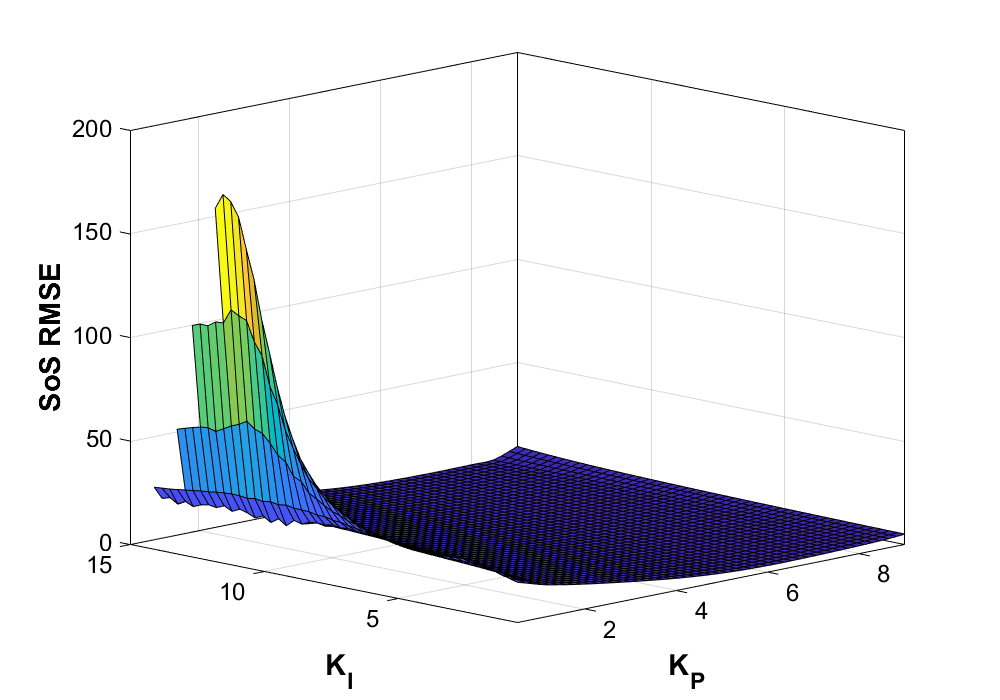

export_fig (savePath,'-eps')



figure('Renderer', 'painters', 'Position', [10 10 1000 700])
risetime04 = zerostrip(strisetime(:,:,ind04));
sfrisetime = fit([risetime04(:,1),risetime04(:,2)],risetime04(:,3),'cubicinterp');
plot(sfrisetime)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
ax.ZAxis.FontSize = 18;
ax.ZAxis.FontName = 'Helvetica';
ax.ZAxis.Color = 'k';
xlabel('K_P','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('K_I','FontName','Helvetica','FontSize',22,'FontWeight','bold')
zlabel('Step Rise Time','FontName','Helvetica','FontSize',22,'FontWeight','bold')
box on
view(-45,15)
savePath =strcat(figurePath,'\Smooth Performance\StRiseTime')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\StRiseTime'

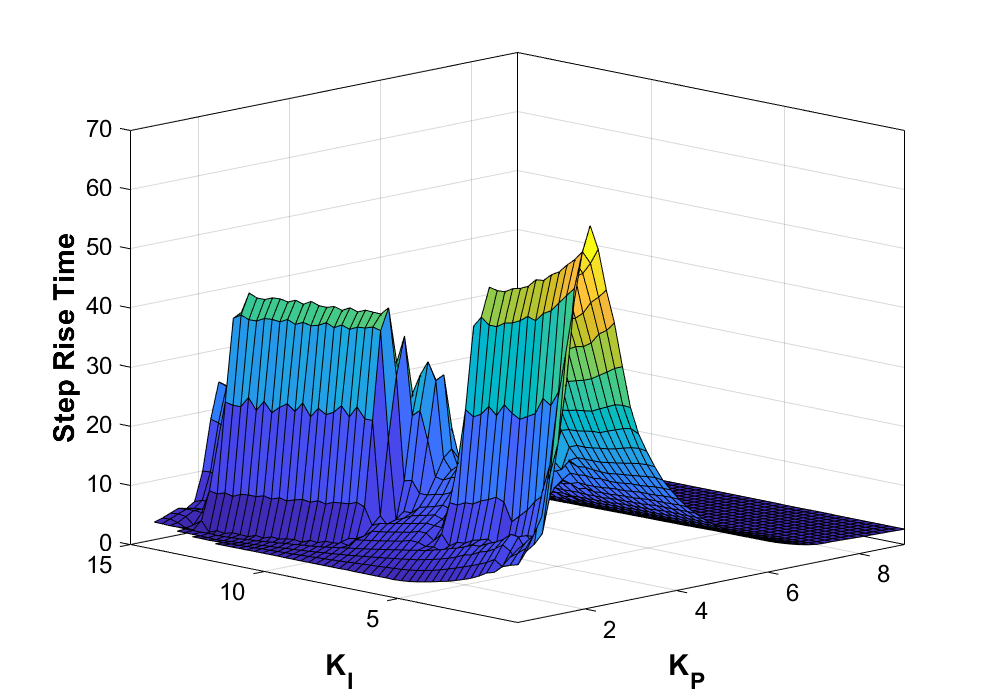

export_fig (savePath,'-eps')



figure('Renderer', 'painters', 'Position', [10 10 1000 700])
settlingtime04 = zerostrip(stsettlingtime(:,:,ind04));
sfsettlingtime = fit([settlingtime04(:,1),settlingtime04(:,2)],settlingtime04(:,3),'cubicinterp');
plot(sfsettlingtime)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
ax.ZAxis.FontSize = 18;
ax.ZAxis.FontName = 'Helvetica';
ax.ZAxis.Color = 'k';
xlabel('K_P','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('K_I','FontName','Helvetica','FontSize',22,'FontWeight','bold')
zlabel('Step Settling Time','FontName','Helvetica','FontSize',22,'FontWeight','bold')
box on
view(-45,15)
savePath =strcat(figurePath,'\Smooth Performance\StSettlingTime')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\StSettlingTime'

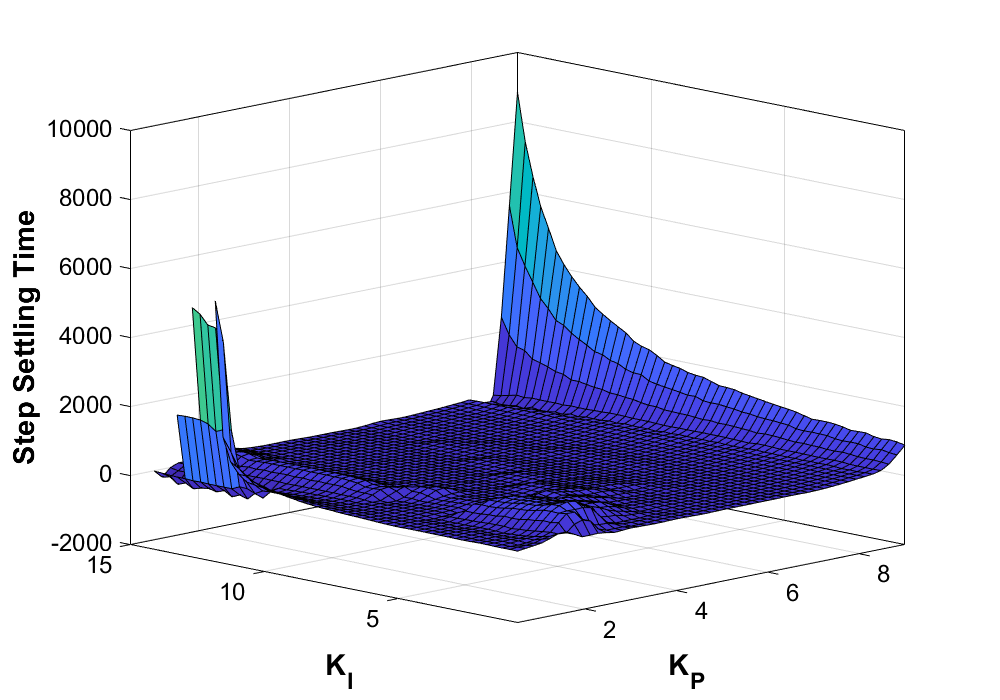

export_fig (savePath,'-eps')



figure('Renderer', 'painters', 'Position', [10 10 1000 700])
overshoot04 = zerostrip(stovershoot(:,:,ind04));
sfovershoot = fit([overshoot04(:,1),overshoot04(:,2)],overshoot04(:,3),'cubicinterp');
plot(sfovershoot)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
ax.ZAxis.FontSize = 18;
ax.ZAxis.FontName = 'Helvetica';
ax.ZAxis.Color = 'k';
xlabel('K_P','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('K_I','FontName','Helvetica','FontSize',22,'FontWeight','bold')
zlabel('Step Overshoot','FontName','Helvetica','FontSize',22,'FontWeight','bold')
box on
view(-45,15)
savePath =strcat(figurePath,'\Smooth Performance\StOvershoot')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\StOvershoot'

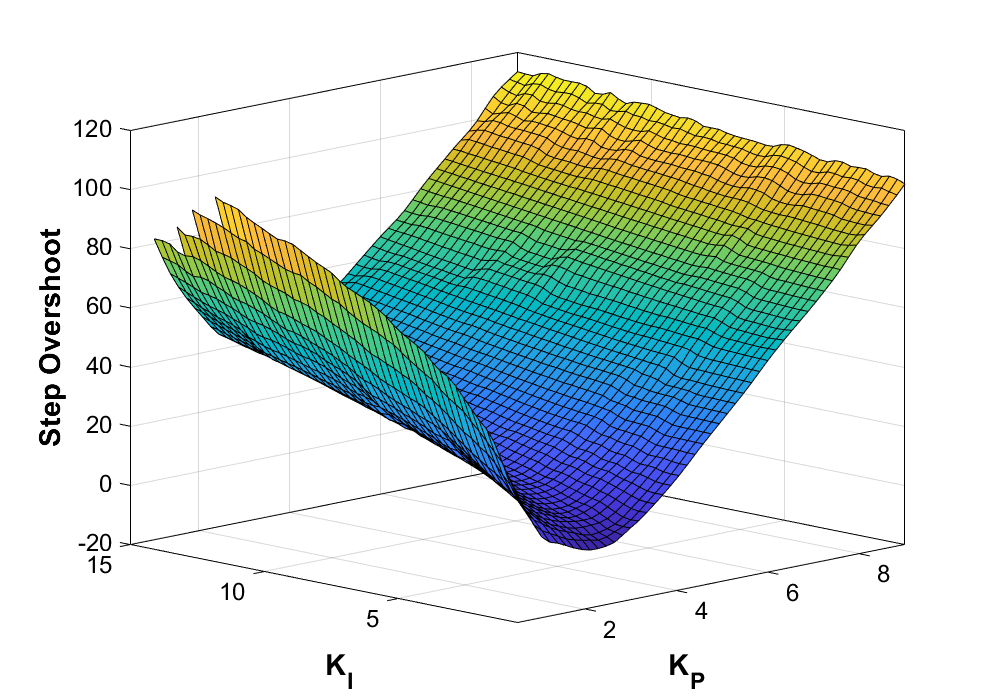

export_fig (savePath,'-eps')

## Normalized, Weighted Surface

weights = [0.2 0.2 0.2 0.2 0.2]'; %Chirp SSE, SoS SSE, Rise, Settling, Overshoot
normchirpses = normalize(chirperror04(:,3),'range');
normsosses = normalize(soserror04(:,3),'range');
normrisetime = normalize(risetime04(:,3),'range');
normsettlingtime = normalize(settlingtime04(:,3),'range');
normovershoot = normalize(overshoot04(:,3),'range');
norms = [normchirpses normsosses normrisetime normsettlingtime normovershoot];
composite = norms*weights;

sfcomposite = fit([overshoot04(:,1),overshoot04(:,2)],composite,'cubicinterp');

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(sfcomposite)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
ax.ZAxis.FontSize = 18;
ax.ZAxis.FontName = 'Helvetica';
ax.ZAxis.Color = 'k';
xlabel('K_P','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('K_I','FontName','Helvetica','FontSize',22,'FontWeight','bold')
zlabel({'Performance Penalty','W = [0.2 0.2 0.2 0.2 0.2]'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')
box on
view(45,20)
savePath =strcat(figurePath,'\Smooth Performance\CompositeEven')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\CompositeEven'

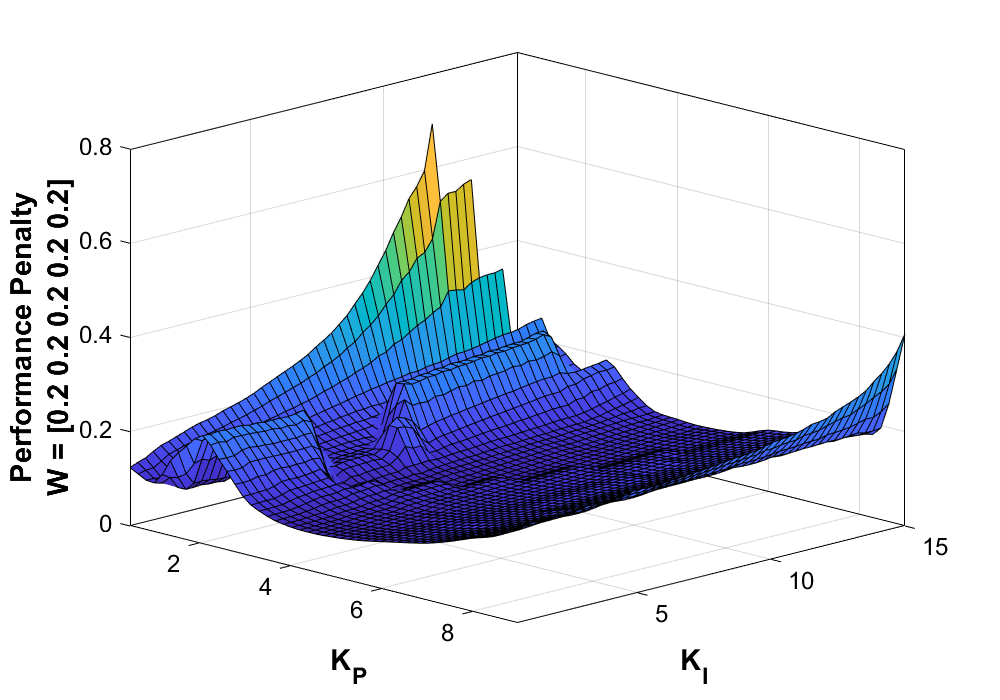

export_fig (savePath,'-eps')



[minimum,index] = min(composite)

minimum = 0.0772

index = 351

minKp_even = overshoot04(index,1)

minKp_even = 3.5000

minKi_even = overshoot04(index,2)

minKi_even = 5


%Fast
weights = [0.5 0.5 0 0 0]'; %Chirp SSE, SoS SSE, Rise, Settling, Overshoot
normchirpses = normalize(chirperror04(:,3),'range');
normsosses = normalize(soserror04(:,3),'range');
normrisetime = normalize(risetime04(:,3),'range');
normsettlingtime = normalize(settlingtime04(:,3),'range');
normovershoot = normalize(overshoot04(:,3),'range');
norms = [normchirpses normsosses normrisetime normsettlingtime normovershoot];
composite = norms*weights;

sfcomposite = fit([overshoot04(:,1),overshoot04(:,2)],composite,'cubicinterp');

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(sfcomposite)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
ax.ZAxis.FontSize = 18;
ax.ZAxis.FontName = 'Helvetica';
ax.ZAxis.Color = 'k';
xlabel('K_P','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('K_I','FontName','Helvetica','FontSize',22,'FontWeight','bold')
zlabel({'Performance Penalty','W = [0.5 0.5 0 0 0]'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')
box on
view(45,20)
savePath =strcat(figurePath,'\Smooth Performance\CompositeSkewed')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\CompositeSkewed'

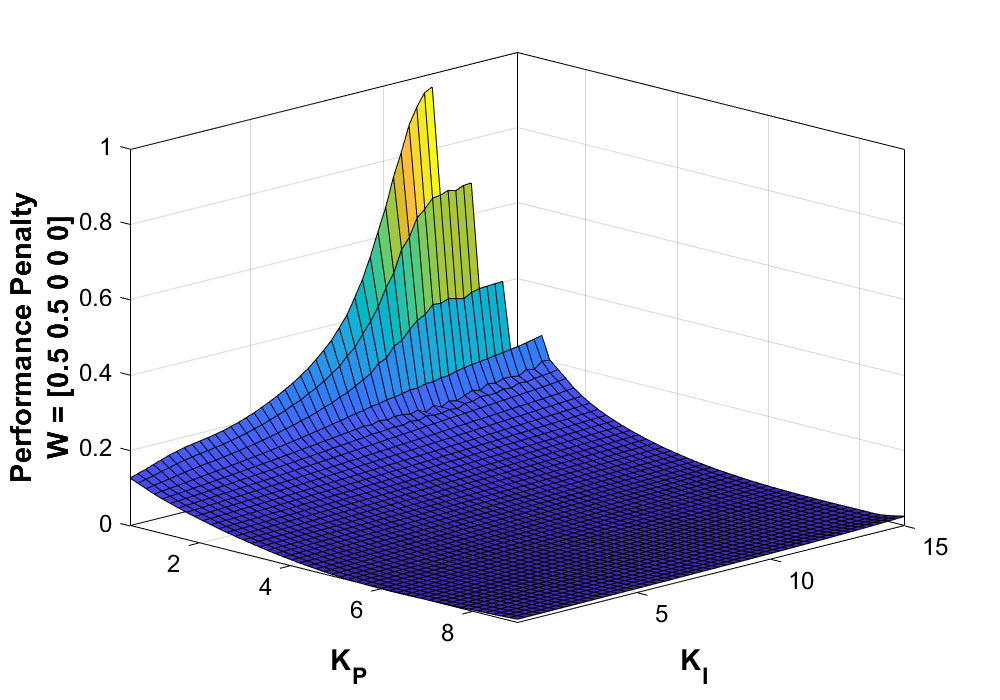

export_fig (savePath,'-eps')



[minimum,index] = min(composite)

minimum = 7.0046e-05

index = 210

minKp_skew = overshoot04(index,1)

minKp_skew = 6

minKi_skew = overshoot04(index,2)

minKi_skew = 0.5000

## Optimal Response Based on weighting

C_tf = tf([minKp_even minKi_even],[1 0]);
%Delay (Pade approximation)
td =.04;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = C_tf*G_plant;
oltf = num*d_tf;
den = (1 + oltf);
cl_tf = num/den;

chirpsim = lsim(cl_tf,chirps_slow,t);
sossim = lsim(cl_tf,sos_slow,t);
stepsim = lsim(cl_tf,stepin,t);

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(t,chirps_slow,t,chirpsim,'LineWidth',1.5)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
legend('Input Angular Velocity (deg/s)', 'Output Angular Velocity (deg/s)')
box on
set(gcf, 'Color', 'w');
savePath =strcat(figurePath,'\Smooth Performance\ResponseEvenChirp')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\ResponseEvenChirp'

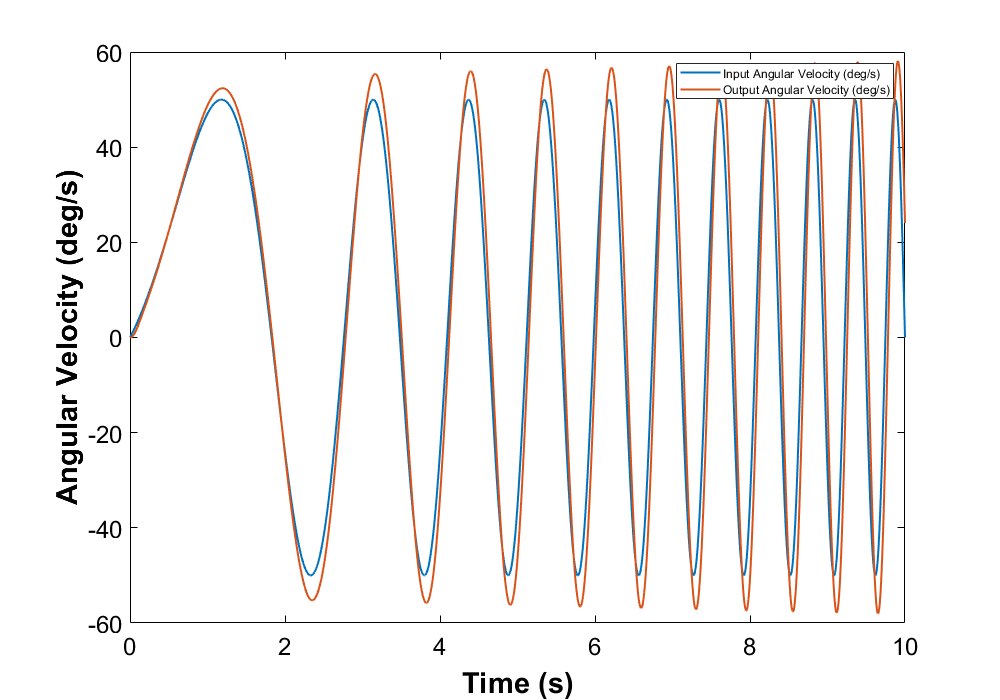

export_fig (savePath,'-eps')


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(t,sos_slow,t,sossim,'LineWidth',1.5)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
legend('Input Angular Velocity (deg/s)', 'Output Angular Velocity (deg/s)')
box on
set(gcf, 'Color', 'w');
savePath =strcat(figurePath,'\Smooth Performance\ResponseEvenSoS')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\ResponseEvenSoS'

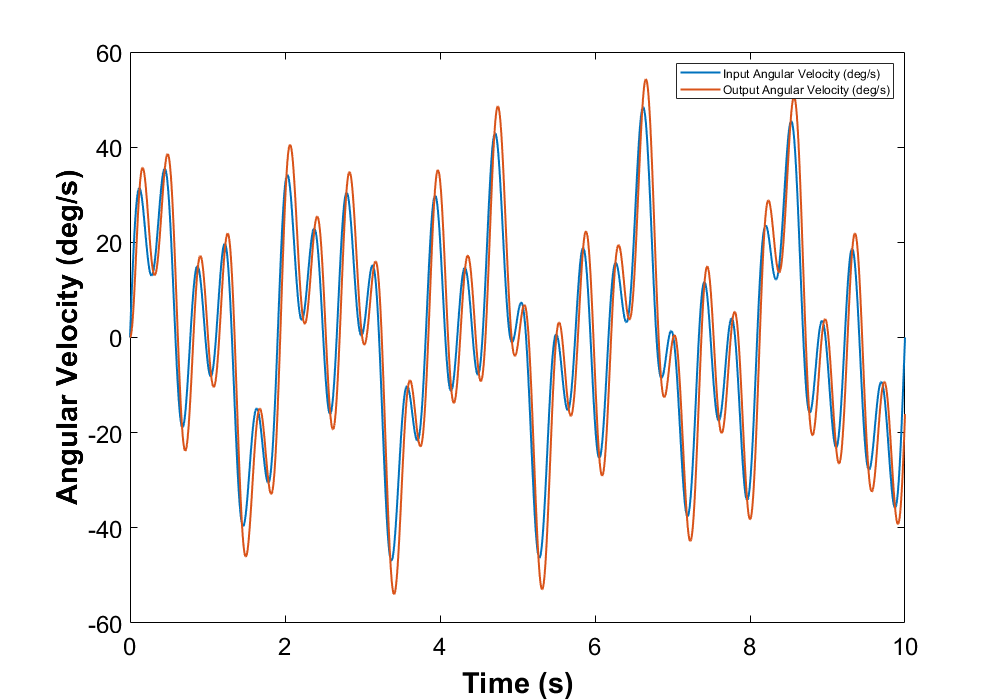

export_fig (savePath,'-eps')


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(t,stepin,t,stepsim,'LineWidth',1.5)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
legend('Input Angular Velocity (deg/s)', 'Output Angular Velocity (deg/s)')
box on
set(gcf, 'Color', 'w');

savePath =strcat(figurePath,'\Smooth Performance\ResponseEvenStep')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\ResponseEvenStep'

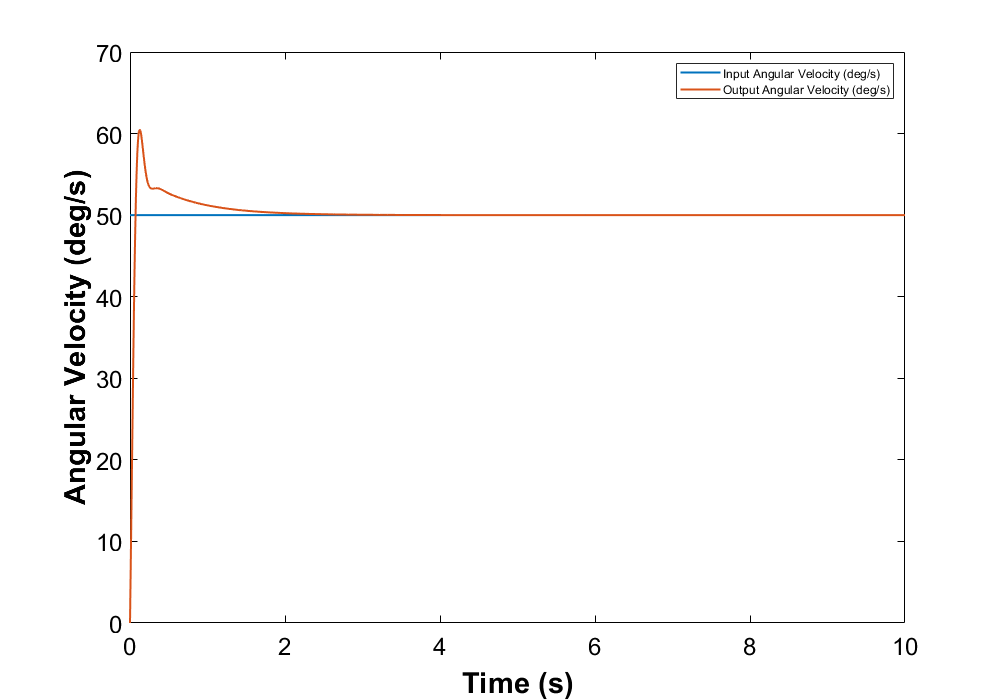

export_fig (savePath,'-eps')


%Skewed weighting
C_tf = tf([minKp_skew minKi_skew],[1 0]);
%Delay (Pade approximation)
td =.04;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = C_tf*G_plant;
oltf = num*d_tf;
den = (1 + oltf);
cl_tf = num/den;

chirpsim = lsim(cl_tf,chirps_slow,t);
sossim = lsim(cl_tf,sos_slow,t);
stepsim = lsim(cl_tf,stepin,t);

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(t,chirps_slow,t,chirpsim,'LineWidth',1.5)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
legend('Input Angular Velocity (deg/s)', 'Output Angular Velocity (deg/s)')
box on
set(gcf, 'Color', 'w');
savePath =strcat(figurePath,'\Smooth Performance\ResponseSkewChirp')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\ResponseSkewChirp'

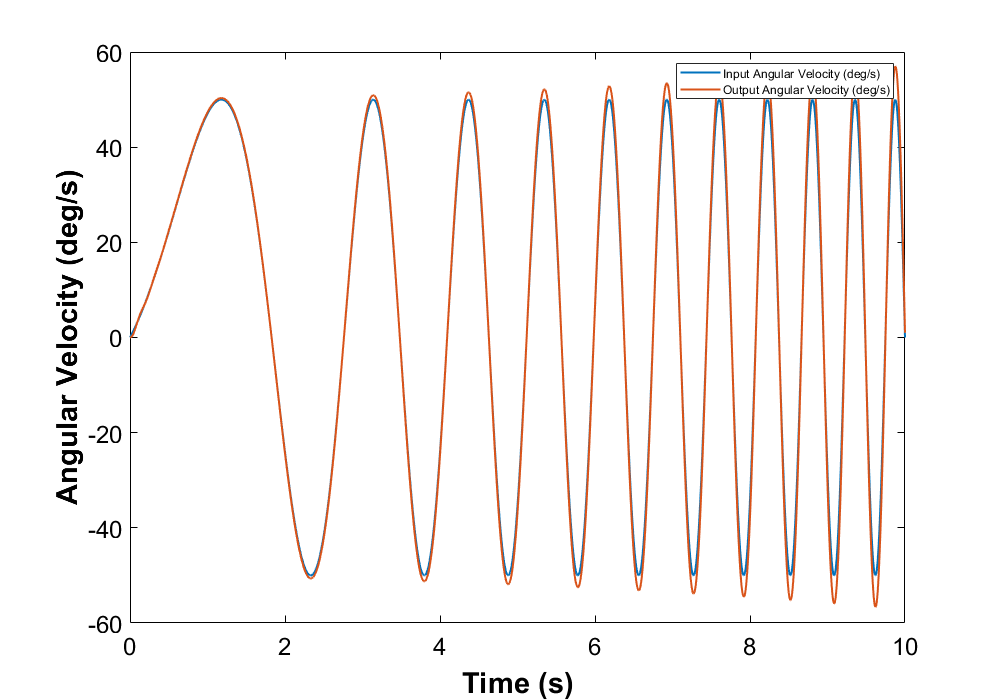

export_fig (savePath,'-eps')


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(t,sos_slow,t,sossim,'LineWidth',1.5)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
legend('Input Angular Velocity (deg/s)', 'Output Angular Velocity (deg/s)')
box on
set(gcf, 'Color', 'w');
savePath =strcat(figurePath,'\Smooth Performance\ResponseSkewSoS')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\ResponseSkewSoS'

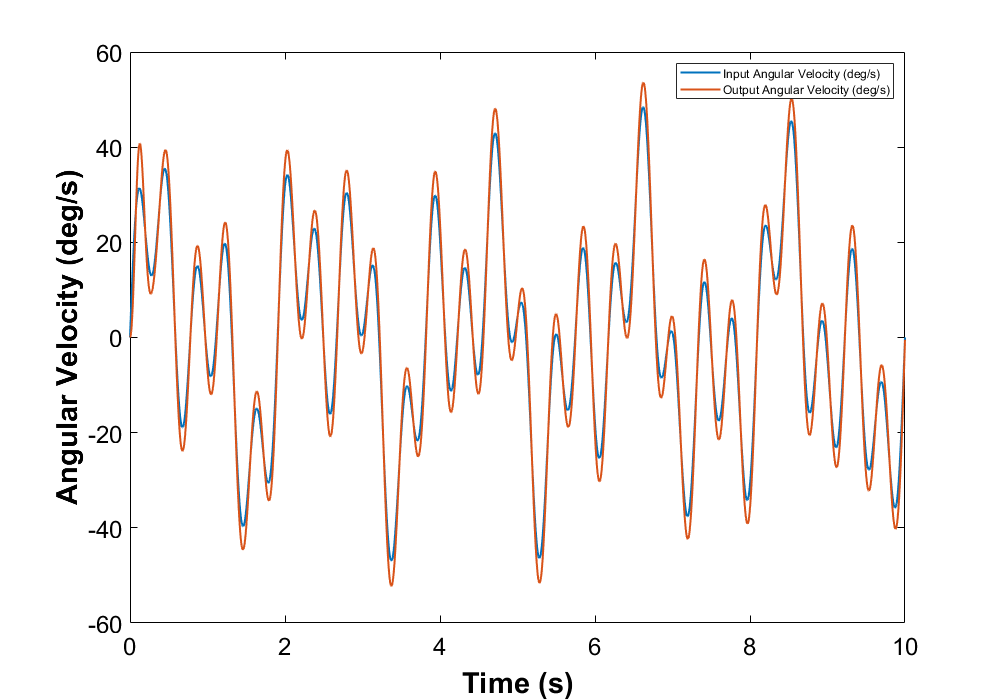

export_fig (savePath,'-eps')


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(t,stepin,t,stepsim,'LineWidth',1.5)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
legend('Input Angular Velocity (deg/s)', 'Output Angular Velocity (deg/s)')
box on
set(gcf, 'Color', 'w');

savePath =strcat(figurePath,'\Smooth Performance\ResponseSkewStep')

savePath = 'C:\Users\Brock\Documents\Smooth_Saccade_Simulation\Common Files\Golden Figures\\Smooth Performance\ResponseSkewStep'

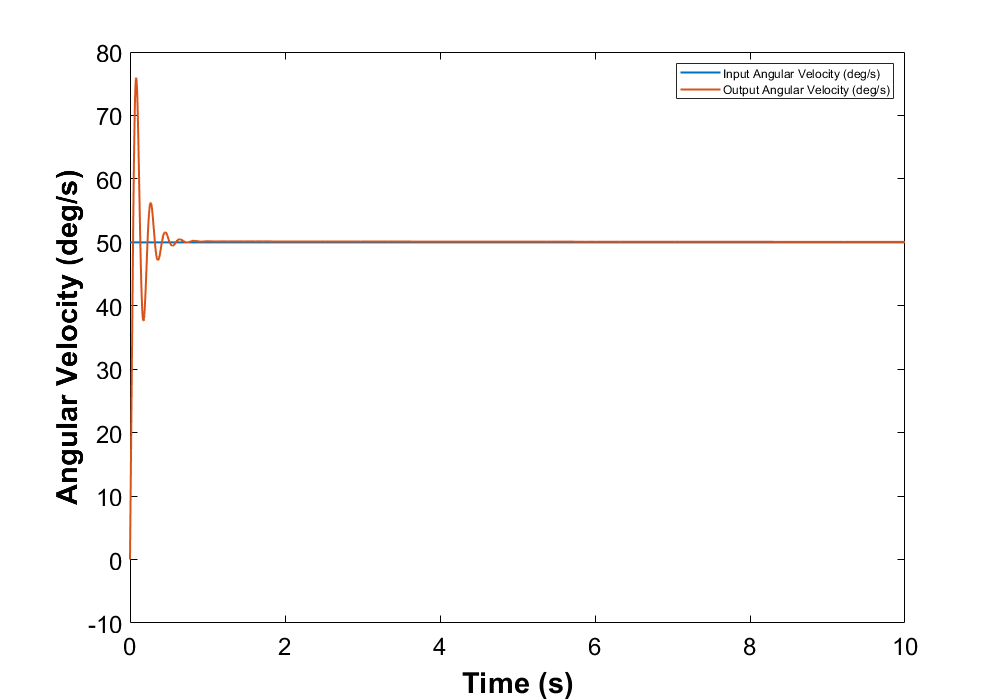

export_fig (savePath,'-eps')

# Smooth System Tracking Error

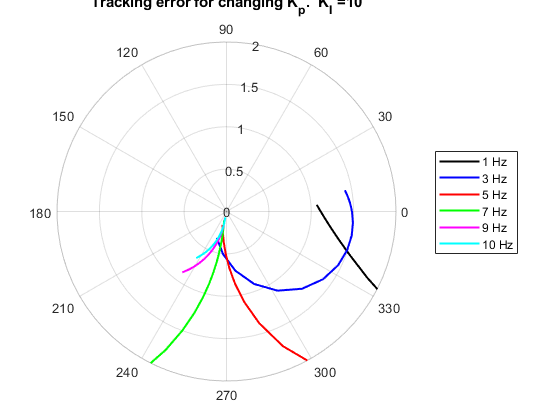

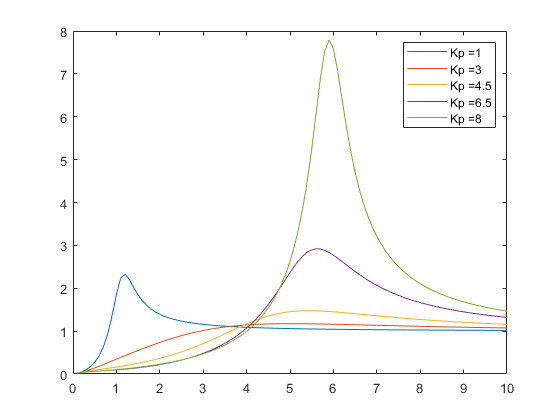

lineColors = [{'k'} {'b'} {'r'} {'g'} {'m'} {'c'}];
selectedFreqIndices = [10 30 50 70 90 100];

%Proportional Gain Sweep
Kp = 1:0.5:8;
Ki = 10;
selectedArrayIndices = round(linspace(1,length(Kp),5));

%Delay (Pade approximation)
td =.04;

[tmagsP,tphasesP] = trackingErrorPlot(G_plant,Kp,Ki,td,0,pureSinTime,pureSin,sinfreqs,lineColors,...
selectedFreqIndices,selectedArrayIndices);

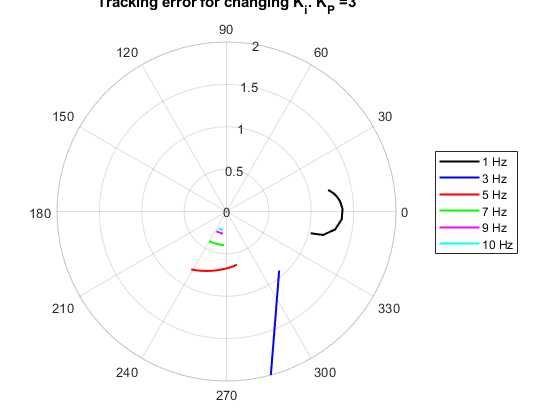

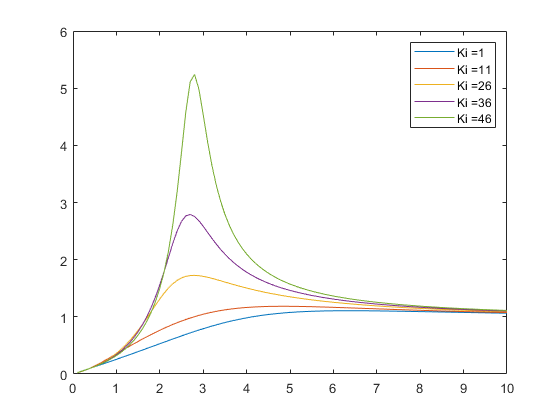


%Integral Gain Sweep
Kp = 3;
Ki = 1:5:50;
selectedArrayIndices = round(linspace(1,length(Ki),5));

%Delay (Pade approximation)
td =.04;

[tmagsI,tphasesI] = trackingErrorPlot(G_plant,Kp,Ki,td,1,pureSinTime,pureSin,sinfreqs,lineColors,...
selectedFreqIndices,selectedArrayIndices);